# **R-factor: Visualize geomechanical changes as a movie**

## Introduction

Several models were generated with COMSOL

- Model 5 - Homogeneous model

- Model 6 - Groningen model, different permeability on top and bottom of the reservoir

- Model 7 - Groningen model, the same permeability on top and bottom of the reservoir

This script visualize changes due to fluid production for Model 5

**Authors**: Ivan Abakumov

**Publication date**: 28th of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

Results = MLD('/home/ivan/Desktop/Comsol/My_model_7_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_7_G_file.mat');

%loops = 101;
%F(loops) = struct('cdata',[],'colormap',[]);


%for tt = 1:1:loops 
tt = 1

tt = 1

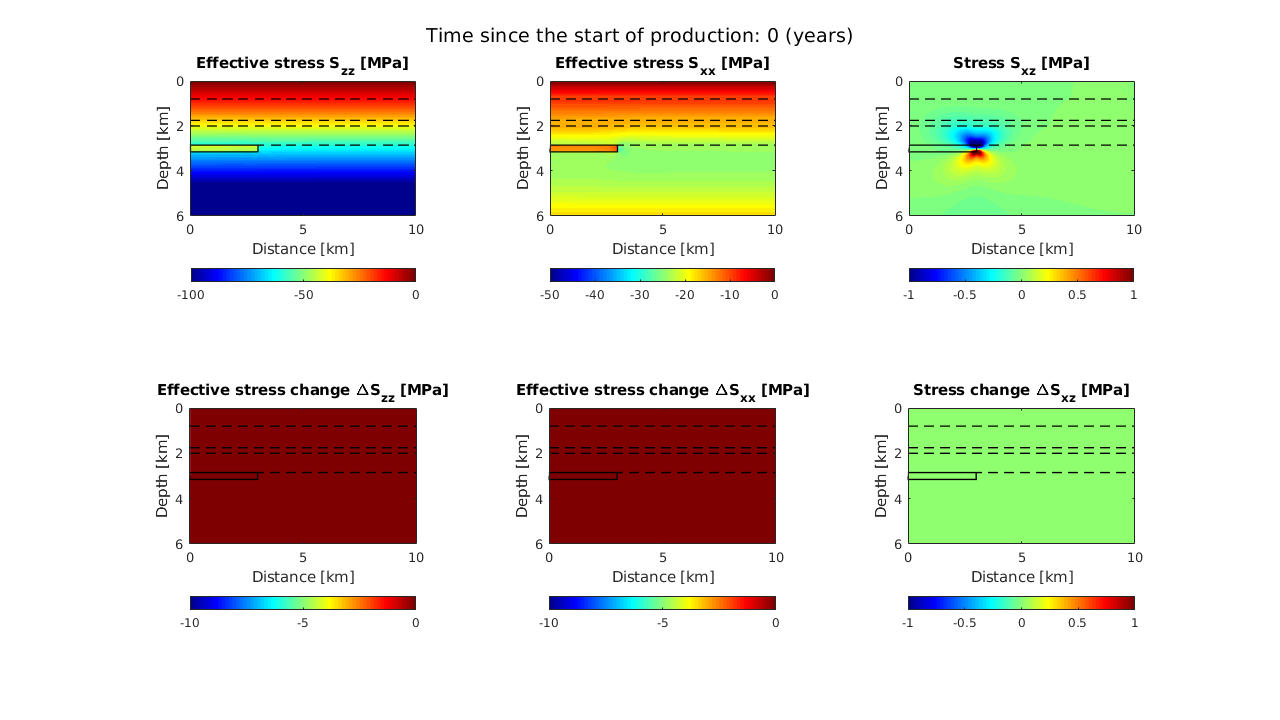


    figure(223)
    fig = figure('Position', [1 1 1280 720]);
    
    
    subplot(2,3,1)
    imagesc(G.xx/1e3, G.zz/1e3, Results.stress_y(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    colormap jet
    c = colorbar;
    c.Location = 'southoutside';
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress S_{zz} [MPa]')
    caxis([-100 0])
    
    subplot(2,3,2)
    imagesc(G.xx/1e3, G.zz/1e3, Results.stress_x(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    c = colorbar;
    c.Location = 'southoutside';
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress S_{xx} [MPa]')
    caxis([-50 0])
    
    subplot(2,3,3)
    imagesc(G.xx/1e3, G.zz/1e3, Results.stress_xy(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    c = colorbar;
    c.Location = 'southoutside';
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Stress S_{xz} [MPa]')
    caxis([-1 1])
    
    subplot(2,3,4)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_y(:,:,tt)'-Results.stress_y(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    c = colorbar;
    c.Location = 'southoutside';
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title(['Effective stress change \DeltaS_{zz} [MPa]'])
    caxis([-10 0])
    
    subplot(2,3,5)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_x(:,:,tt)'-Results.stress_x(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    c = colorbar;
    c.Location = 'southoutside';
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress change \DeltaS_{xx} [MPa]')
    caxis([-10 0])
    
    subplot(2,3,6)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_xy(:,:,tt)'-Results.stress_xy(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
    plot(linspace(0,0,101),linspace(0,3,101),'w-')
    plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
    plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
    colormap jet
    c = colorbar;
    c.Location = 'southoutside';
    axis('equal')
    axis([0 10 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Stress change \DeltaS_{xz} [MPa]')
    caxis([-1 1])
    
    sgtitle(['Time since the start of production: ' num2str(G.tt(tt),2) ' (years)'] )



%    F(tt) = getframe(gcf);
%    pause(0.03);
%    disp(tt)
%end

## Save Movie

v = VideoWriter('/home/ivan/Desktop/test3','Motion JPEG AVI');
v.FrameRate = 5;
v.Quality = 100;
open(v);
writeVideo(v,F);
close(v);